# 

## MATLAB Fundamentals: Tutorial 02, Exercise 05

### August 2023

# 5.  ODE Solving and Graphics  

Consider a pendulum subject to gravity and damping, as shown in Figure 5-1.

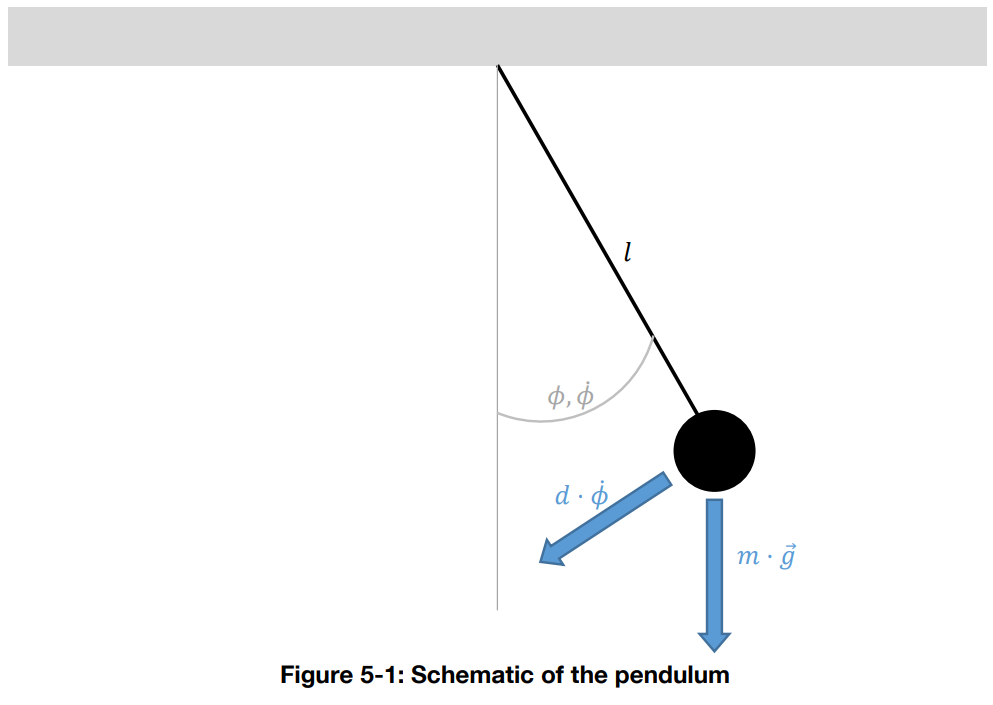

The pendulum’s nonlinear dynamics can be written as follows:


$$\ddot \phi = - \frac gl \sin\phi - \frac d {ml^2} \dot \phi$$


with the Earth’s gravitation $g$, the mass $m$, the length of the rod $l$ and a damping constant $d$. For small angles $\phi$, we can assume $\sin\phi \approx \phi$, which leads to the following linear equation:


$$\ddot \phi = - \frac gl \phi - \frac d {ml^2} \dot \phi$$


**Exercise**

(1)     Solve the linear pendulum differential equation in MATLAB symbolic language. Assume $\phi(0) = 1 \text{rad}$ and $\dot \phi(0) = 0$.

syms phi(t) g l d m;
ode = diff(phi, t, 2) == - (g/l) * phi - (d / (m * l^2)) * diff(phi, t);
phi0 = 1; dphi0 = 0; 
phi_sol = dsolve(ode, phi(0) == phi0, diff(phi, t) == dphi0);

(2)    Take the solution obtained and insert the following values:

$l = 10 \text m \\ m = 5 \text{kg} \\ g = 9,81 \text{m s}^{-2} \\ d = 50 \text{kg m}^2\text{ s}^{-1}$s

(3)    Compute the pendulum angle $\phi(5\text s)$ and give a 40-digit numeric representation. Note down the first three and the last three digits.

### *Hint:* Use `vpa`.

(4)    Make a 3D-plot for $t \in \left[0; 40 \right]$. Plot $l \sin \phi$ on the x-axis, $t$ on the y-axis and $-l \cos\phi$ on the z-axis.

(5)    Look at the plot from different angles. Note that when you look along the y-axis onto the xz-plane, you can see the pendulum oscillation.

Technische Universität München – Lehrstuhl für Flugsystemdynamik – MATLAB Fundamentals: Tutorial 02 – August 2023